clear;
close all;

path=uigetdir('SEO'); %load DICOM images from you pc
[V,spatial,dim]=dicomreadVolume(fullfile(path));
%spatial returns a structure that describes the location, resolution, and orientation of the input DICOM data
%dim returns the dimension that has the largest amount of offset between two adjacent slices in the input DICOM data
V=squeeze(V); %returns an array with the same elements as the input array A, but with dimensions of length 1 removed


spatial = struct with fields:
       PatientPositions: [247×3 double]
          PixelSpacings: [247×2 double]
    PatientOrientations: [2×3×247 double]
              ImageSize: [512 512 247]


figure
vol1=volshow(V)

vol1 =   volshow with properties:

                 Parent: [1×1 Panel]
               Alphamap: [256×1 double]
               Colormap: [256×3 double]
               Lighting: 1
        IsosurfaceColor: [1 0 0]
               Isovalue: 0.5000
               Renderer: 'VolumeRendering'
         CameraPosition: [4 4 2.5000]
         CameraUpVector: [0 0 1]
           CameraTarget: [0 0 0]
        CameraViewAngle: 15
        BackgroundColor: [1 1 1]
           ScaleFactors: [1 1 1]
    InteractionsEnabled: 1


vol1.BackgroundColor='white';
vol1.ScaleFactors=[spatial.PixelSpacings(1, 1), spatial.PixelSpacings(1, 2)  abs(spatial.PatientPositions(1,3)-spatial.PatientPositions(3,3))]; %resize the image
vol1.Isovalue=0.13; %change contrast value
vol1.Renderer='Isosurface';

figure
vol2=volshow(V)

vol1 =   volshow with properties:

                 Parent: [1×1 Panel]
               Alphamap: [256×1 double]
               Colormap: [256×3 double]
               Lighting: 1
        IsosurfaceColor: [1 0 0]
               Isovalue: 0.5000
               Renderer: 'VolumeRendering'
         CameraPosition: [4 4 2.5000]
         CameraUpVector: [0 0 1]
           CameraTarget: [0 0 0]
        CameraViewAngle: 15
        BackgroundColor: [1 1 1]
           ScaleFactors: [1 1 1]
    InteractionsEnabled: 1


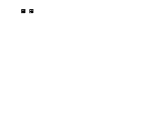

vol2.BackgroundColor='white';
vol2.ScaleFactors=[spatial.PixelSpacings(1, 1), spatial.PixelSpacings(1, 2)  abs(spatial.PatientPositions(1,3)-spatial.PatientPositions(3,3))];
vol2.Isovalue=0.274;
vol1.Renderer='Isosurface';

figure
for i=1:246
    subplot(16,16,i)
    XY = V(:,:,i);
    imshow(XY,[],'Border','tight');
end


figure
vol3=sliceViewer(V)

vol3 =   sliceViewer with properties:

             SliceDirection: [0 0 1]
                SliceNumber: 124
                     Parent: [1×1 Panel]
                   Colormap: [256×3 double]
               DisplayRange: [0 4095]
               ScaleFactors: [1 1 1]
    DisplayRangeInteraction: 'on'


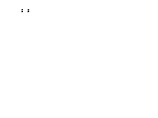


figure
for ii=1:512
    subplot(23,23,ii)
    XZ = squeeze(V(ii,:,:));
    imshow(XZ,[],'Border','tight');
end

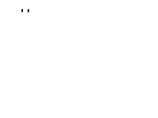


figure
for iii=1:512
    subplot(23,23,iii)
    XZ = squeeze(V(:,iii,:));
    imshow(XZ,[],'Border','tight');
end